#### Evolution of motor effectiveness with skew angle

G1_00 = [-1.62,1.802,0.294;
    -9.848, 0.114, -0.172;
    -0.67,-1.687,0.196;
    8.109,0.208,-0.179];
G2_00 = [0.012,-0.017,0.014,-0.012];
G1_15 = [-0.498,2.038,0.380;
    -10.925,-0.031,-0.130;
    -0.946,-1.709,0.301;
    8.452,0.933,-0.085];
G2_15 = [0.0079,-0.018,0.0088,-0.012];
G1_30 = [-0.36,1.759,0.319;
    -7.792,-1.181,-0.406;
    -0.778,-2.015,0.165;
    6.802,1.286,-0.062];
G2_30 = [0.015,-0.001,0.011,-0.007];
G1_45 = [1.334,1.734,0.307;
    -4.808,-1.783,-0.354;
    -1.085,-1.821,0.277;
    3.402,2.148,0.047];
G2_45 = [0.014,-0.005,0.015,-0.002];
G1_55 = [0.258,2.224,0.388;
    -3.396,-2.358,-0.411;
    -1.373,-2.161,0.286;
    3.374,1.881,-0.399];
G2_55 = [0.013,0.007,0.01,-0.004];
G1_65 = [0.408,2.115,0.33;
    -1.605,-2.083,-0.363;
    -0.79,-2.111,0.184;
    1.975,1.884,-0.269];
G2_65 = [0.013,-0.005,0.017,-0.006];
G1_75 = [-0.139,1.687,0.395;
    -1.103,-1.186,-0.419;
    -0.007,-1.842,0.26;
    1.244,1.203,-0.388];
G2_75 = [0.007,0.001,0.01,0.005];
G1_70 = [-0.248,1.306,0.326;
    -1.367,-1.404,-0.272;
    0.07,-1.869,0.051;
    1.4,1.209,-0.29];
G2_70 = [0.018,-0.008,0.02,0.003];
skew = [0,15,30,45,55,65,70,75];
act_names = ["Motor Front","Motor Right","Motor Back","Motor Left","Aileron Left", "Aileron Right","Elevator","Rudder","Push Motor","Rot Mech"];


Plots to understand evolution

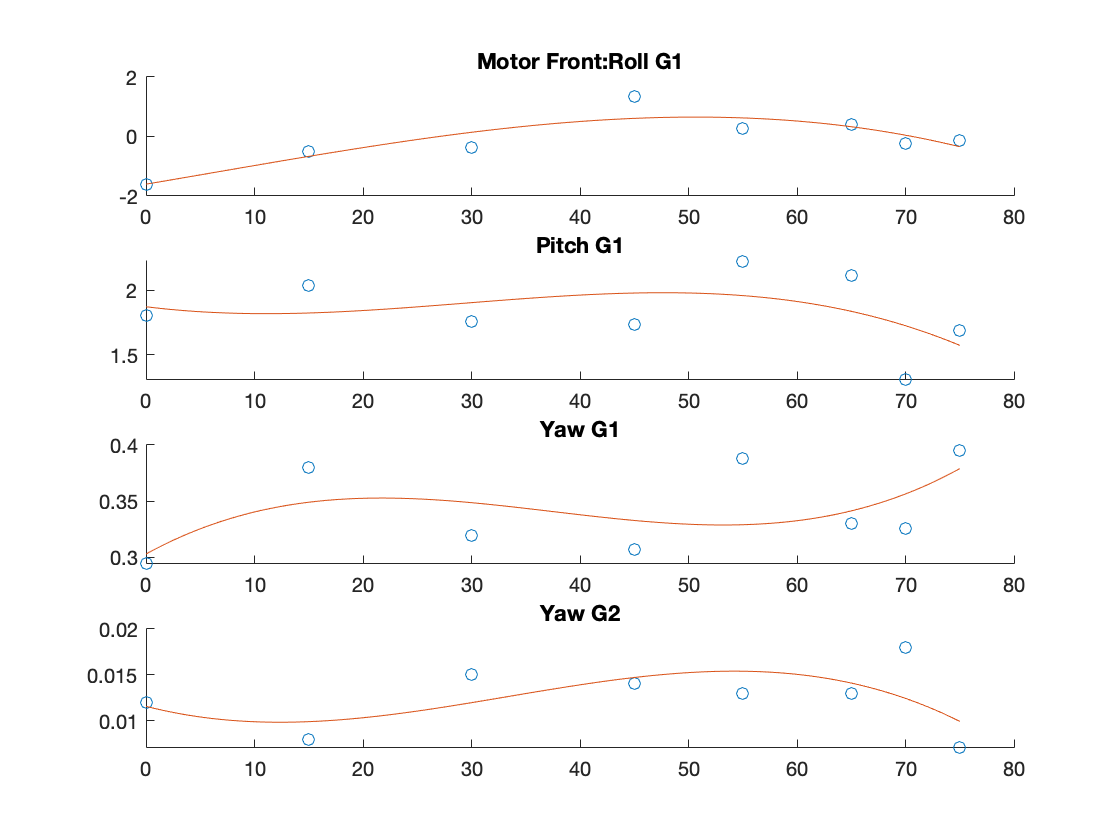

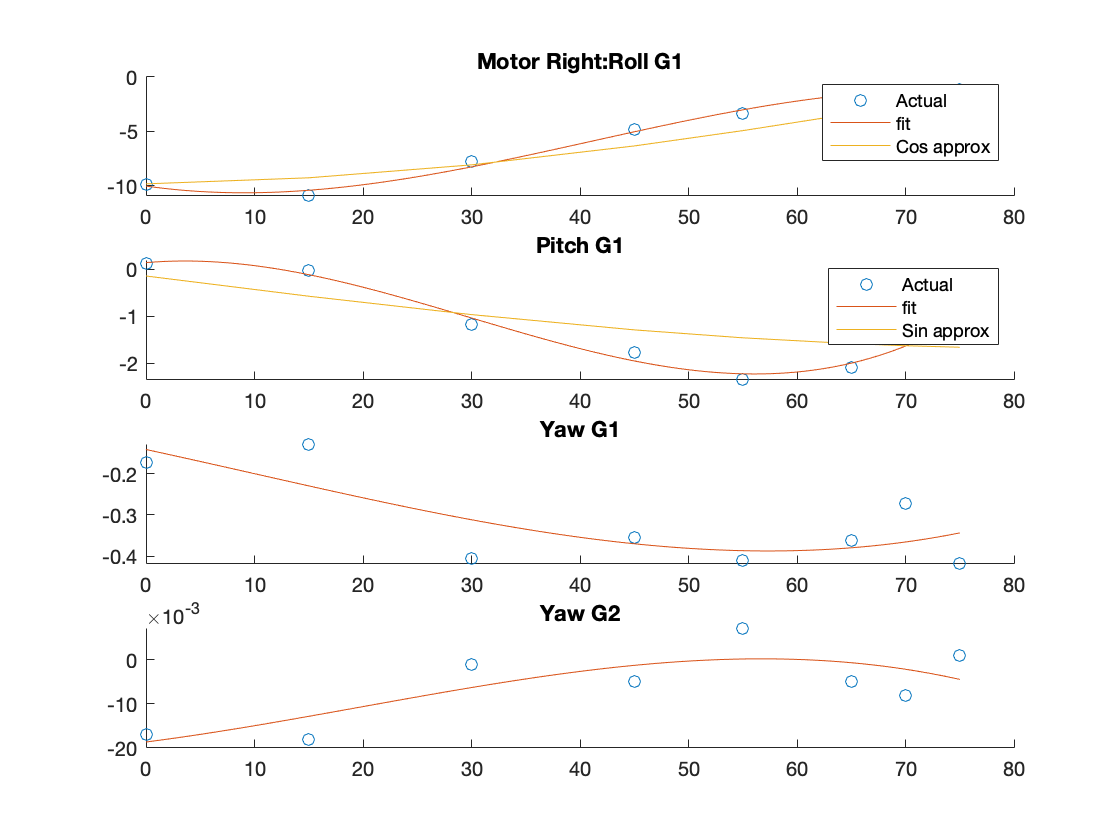

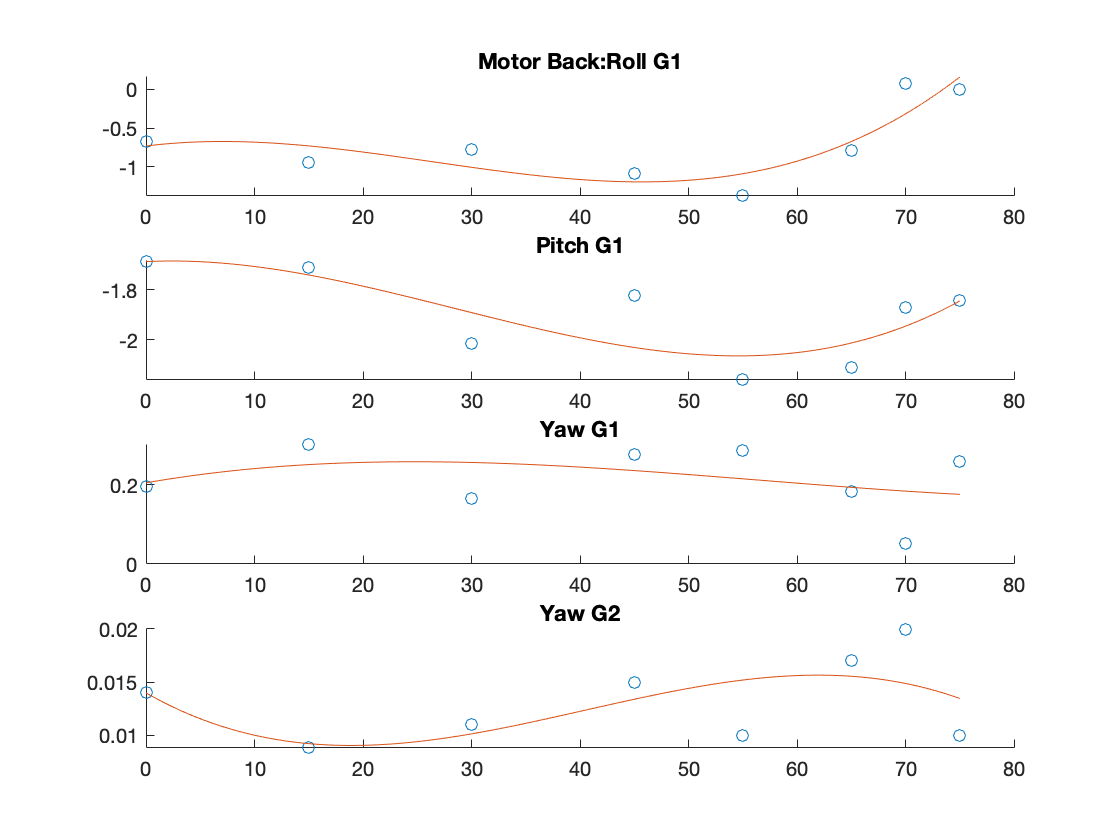

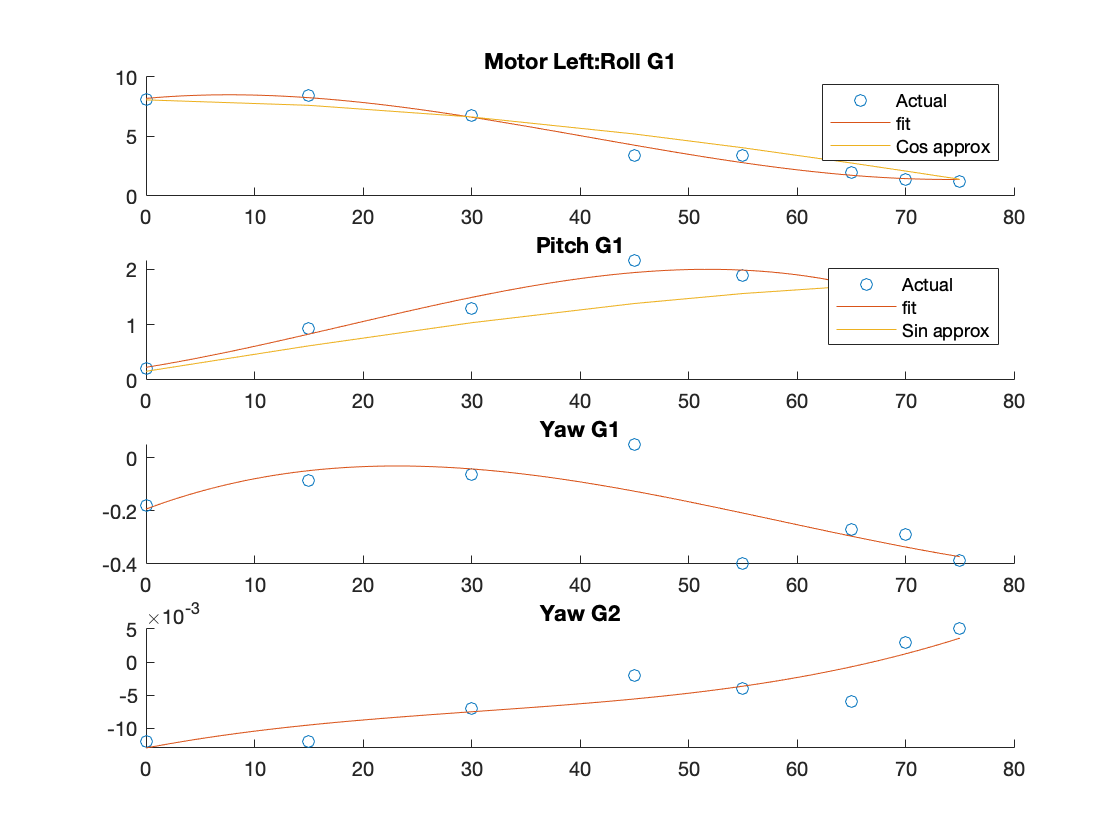

x = linspace(min(skew),max(skew));
order = 3;
G1_q_90 = [G1_00(3,2),G1_00(1,2)];
for i = 1:4

    data = [G1_00(i,:);G1_15(i,:);G1_30(i,:);G1_45(i,:);G1_55(i,:);G1_65(i,:);G1_70(i,:);G1_75(i,:)];
    data2 = [G2_00(i),G2_15(i),G2_30(i),G2_45(i),G2_55(i),G2_65(i),G2_70(i),G2_75(i)];
    %fprintf('ACTUATOR : %s \n',act_names(i))
    figure(i)
    clf 
    ax1 = subplot(4,1,1);
    scatter(skew,data(:,1))
    hold on
    plot(x,polyval(polyfit(skew,data(:,1),order),x))
    if mod(i,2)==0
        
        plot(skew,data(1,1).*cos(deg2rad(skew+5)))
        legend("Actual","fit","Cos approx")
        
    end
    hold off
    title(strcat(act_names(i),":Roll G1"))
    %legend("00","15","30","45")

    ax2 = subplot(4,1,2);
    scatter(skew,data(:,2))
    hold on
    plot(x,polyval(polyfit(skew,data(:,2),order),x))
    if mod(i,2)==0
        
        plot(skew,G1_q_90(fix(i/2)).*sin(deg2rad(skew+5)))
        legend("Actual","fit","Sin approx")
        
    end
    hold off
    title("Pitch G1")
    %legend("00","15","30","45")

    ax3 = subplot(4,1,3);
    scatter(skew,data(:,3))
    hold on
    plot(x,polyval(polyfit(skew,data(:,3),order),x))
    hold off
    title("Yaw G1")
    %legend("00","15","30","45")

    ax4 = subplot(4,1,4);
    scatter(skew,data2)
    hold on
    plot(x,polyval(polyfit(skew,data2,order),x))
    hold off
    title("Yaw G2")
    %legend("00","15","30","45")
    linkaxes([ax1,ax2,ax3,ax4],'x');
    %sgt = sgtitle(act_names(i)) ;
    
end